# Continuous Random Variables

***Author****: Ward Nickle, Humboldt State University*

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and they will generate errors if run out of order.

The   icon refers to an interactive activity that you will find in this script. 

## Background

Coins, dice, and playing cards are commonly used to describe discrete random variables and their associated probability distributions. For example, if we consider the number of heads in two coin tosses, there are a fixed number of possible outcomes and a probability for each. 

On the other hand, continuous random variables can take on an infinite number of possible values. For examples, consider the amount of time it takes to start a computer or the depth of a water body at a randomly selected point. The values of these variables are obtained by measuring (as opposed to counting). As a consequence, it is not useful to think of a continuous random variable taking on a single value, but very useful to think of the probablity of such a variable taking on a value within a given interval.

## Uniform Distribution

A uniform random variable is one in which every value is equally probable. Due to this quality, the shape of the distribution is rectangular. There are two parameters that describe the shape of the distribution, *a*, the minimum value of the random variable, and *b*, its maximum value. One can therefore determine the mean based on the average of *a* and *b*, that is, the midpoint.


$$\mu =\frac{a+b}{2}$$


The standard deviation of a uniform distribution is given by the following formula:


$$\sigma =\sqrt{\frac{{\left(b-a\right)}^2 }{12}}$$


Similarly, the probability of the random variable can be found by using the area formula for a rectangle, the range of the distribution, and the fact that the total area is 1. Since the base of the rectangle is the range, $b-a$, and the area is 1, it follows that the height is $\frac{1}{b-a}$. With continuous random variables, probability is equal to the area under the curve formed by the probability distribution.

Because the random variable is continuous, it can assume infinitely many values. The probability that x is a particular value is 0, because this region has no width and is therefore one-dimensional and has no area. Instead we consider the probability that x is between two values, $x_1$ and $x_2$, and find the area of the corresponding rectangle. The probability is then given by the following formula:


$$P\left(x_1 <X<x_2 \right)=\textrm{base}*\textrm{height}=\left(x_2 -x_1 \right)\frac{1}{b-a}$$


 **Example**

Suppose the wait time to be served at a local bank is uniformly distributed between 4 and 10 minutes. What is the probability that a customer will be served in less than 6 minutes? As with all continuous random variables, we are interested in the cumulative density, that is, the probability that the random variable is in a range of values. Thus, we employ the continuous uniform cumulative distribution function, [p = unifcdf(x,a,b)](https://www.mathworks.com/help/stats/unifcdf.html). 

unifcdf(6,4,10)

ans = 0.3333

What is the likelihood that the customer will have to wait longer than 5 minutes? We can use the complement rule to answer this question, since $P\left(X>5\right)=1-P\left(X<5\right)$.

1-unifcdf(5,4,10)

ans = 0.8333

Alternatively, we could use the 'upper' argument in the cdf.

unifcdf(5,4,10,'upper')

ans = 0.8333

  **Task**

The helper function `PlotUniformDist` draws the probability density function (pdf) and displays $P\left(x_1 <X<x_2 \right)$ for a uniform random variable. The bounds on *x*, *a* and *b*, must be real numbers where $a<b$. The probability is shown for values of *x* between $x_1$ and $x_2$, where $x_1 <x_2$.

Enter an appropriate value in each text box below to answer one of the questions in the example above. Click the **Run** button to visualize the solution.

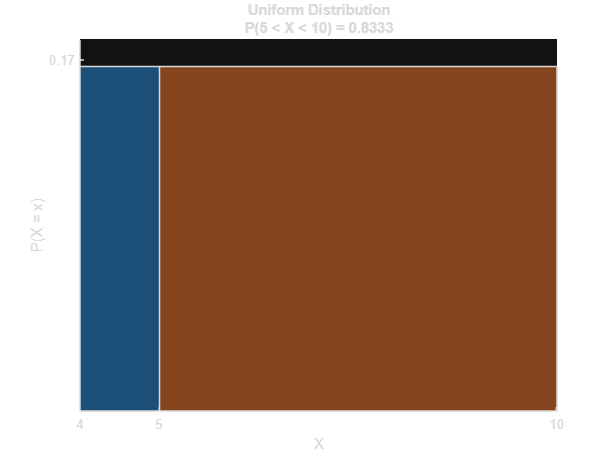

 
a = 4; % min of distribution
b = 10; % max of distribution
x1 = 5; % min of interval
x2 = 10; % max of interval
PlotUniformDist(a,b,x1,x2)

## Normal Distribution

The most common distribution for a continuous random variable is the normal distribution, which has many distinguishing qualities. Normal distributions are bell-shaped and symmetric with tails that approach the x-axis asymptotically. Because they are symmetric, the mean and median are equal and are the center of the distribution. Given the bell-shape, as we move away from the mean, the height of the distribution decreases, which implies that these values are less likely than the mean. Finally, because normal distributions are asymptotic, when we get far enough away from the mean, the height of the curve approaches 0. There are two parameters that describe a normal distribution entirely: the mean, $\mu$, and the standard deviation, $\sigma$. The normal distribution is given by the following formula:


$$P\left(x\right)=\frac{1}{\sigma \sqrt{2\pi }}e^{-\left\lbrack \frac{{\left(x-\mu \right)}^2 }{2\sigma^2 }\right\rbrack }$$


 **Example**

A recent USDA report suggests that the average family of four spends an average of $218 per week on food, with a standard deviation of $24. Assuming the cost is normally distributed, what percent of families of four spend more than $250 per week on food? We can answer this question with the normal cumulative distribution function, [`p = normcdf(x,mu,sigma)`](https://www.mathworks.com/help/stats/normcdf.html#d120e513735). As above, since we are interested in the upper-tail probability, we can use the complement of the lower-tail probability.

1-normcdf(250,218,24)

ans = 0.0912

Again, it would be equivalent to use the `'upper'` argument.

normcdf(250,218,24,'upper')

ans = 0.0912

Suppose we were interested in the amount of money spent by families in the 99th percentile, that is, the value of x that corresponds to a lower-tail probability of 0.99. This is of common interest and is found by using the normal inverse cumulative distribution function, [`x = norminv(p,mu,sigma)`](https://www.mathworks.com/help/stats/norminv.html#d120e515658). Recall that inverse functions trade domain and range, so if we are interested in a value of x given p, we are, in essesence, going in reverse.

norminv(0.99,218,24)

ans = 273.8323

  **Task**

The helper function `PlotNormalDist` draws the probability density function (pdf) and displays $P\left(x_1 <X<x_2 \right)$ for a normal random variable. `mu` can be any real number, but `sigma`, must be non-negative. The probability is shown for values of *x* between $x_1$ and $x_2$, where $x_1 <x_2$.

Enter an appropriate value in each text box below to answer one of the questions in the example above. Click the **Run** button to visualize the solution.

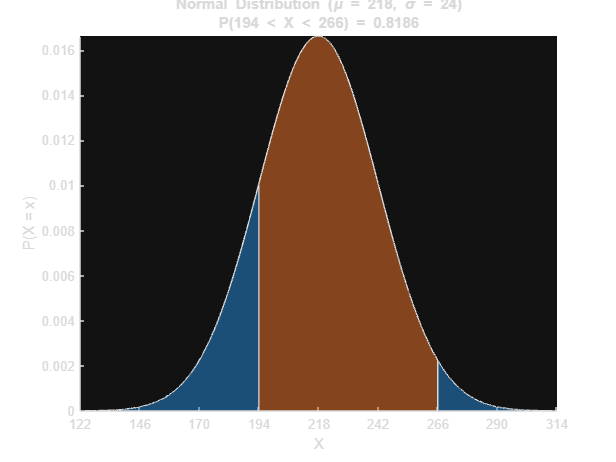

 
mu = 218; % mean of distribution
sd = 24; % sd of distribution
x1 = 194; % min of interval
x2 = 266; % max of interval
PlotNormalDist(mu,sd,x1,x2)

## Standard Normal Distribution

Since there are infinitely many possible normal distributions, it follows that one may wish to standardize a normal distribution to provide a consistent perspective. That is the motivation of the standard normal distribution. The mean of the standard normal distribution is 0, and the standard deviation is 1. To transform a normal random variable to a standard normal variable, we calculate a z-score, sometimes called a z value.


$$z=\frac{x-\mu }{\sigma }$$


In words, a z-score is the number of standard deviations that x is away from its mean. Sign indicates direction, so negative z-scores represent values of x that are below the mean, and positive z-scores represent values of x that are above the mean. Z-scores provide a standard way of viewing a value of a normal random variable. Using the Empirical Rule, which asserts that approximately 68% of the observations are within $\pm$1 standard deviation of the mean, and that 95% of the observations are within $\pm$2 standard deviations of the mean, one can immediately infer a likelihood associated with a particular z-score.

 **Example**

A pregnancy that lasts between 252 days and 298 days is considered full-term. If pregnancy is normally distributed with a mean of 272 days and a standard deviation of 9 days, what proportion of pregnancies are full-term? What are the z-scores for 252 days and 298 days? To find the proportion, we don't need to standardize the variable, but if we do it provides insight into the number of standard deviations the values are from their mean. The z-scores can be found using arithmetic.

z1 = (252-272)/9

z1 = -2.2222

z2 = (298-272)/9

z2 = 2.8889

Now the proportion can be found using the [`p = normcdf(x)`](https://www.mathworks.com/help/stats/normcdf.html?s_tid=srchtitle#d120e513700) function, which assumes a mean of 0 and an sd of 1, that is, the standard normal distribution. Note that this function reports the area to the left of its input, so we should subtract the area to the left of z1 from the area to the left of z2. In symbols, $P\left(z_1 <Z<z_2 \right)=P\left(Z<z_2 \right)-P\left(Z<z_1 \right)$.

normcdf(z2)-normcdf(z1)

ans = 0.9849

  **Task**

The helper function `PlotNormalDist` draws the probability density function (pdf) and displays $P\left(x_1 <X<x_2 \right)$ for a ***standard*** normal random variable. The probability is shown for values of *x* between $x_1$ and $x_2$, where $x_1 <x_2$.

Enter an appropriate value in each text box below to answer one of the questions in the example above. Click the **Run** button to visualize the solution.

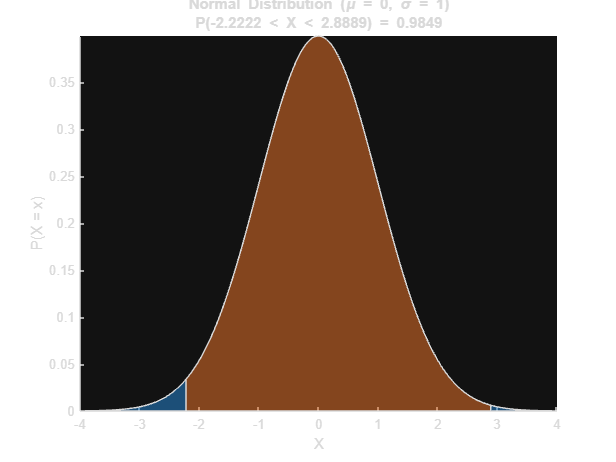

 
mu = 0; % mean of distribution
sd = 1; % sd of distribution
x1 = -2.2222; % min of interval
x2 = 2.8889; % max of interval
PlotNormalDist(mu,sd,x1,x2)

## Exponential Distribution

The exponential distribution is used to find the time between events that occur in a sequence. The events are considered independent and occur with a constant rate. The exponential distribution is positively skewed and defined by one parameter, $\lambda$ (lambda), the rate parameter, which is equal to $\frac{1}{\mu }$, where $\mu$ is the mean arrival time. The probability is given by either of the following:


$$P\left(x\right)=\frac{1}{\mu }e^{\frac{-x}{\mu }} =\lambda e^{-\lambda x}$$


 **Example**

Suppose the time it takes to start a computer follows an exponential distribution with a mean of 27 seconds. What is the probability the computer will start in less than 15 seconds? Let's use the exponential cumulative density function, [`p = expcdf(x,mu)`](https://www.mathworks.com/help/stats/expcdf.html#d120e235154).

expcdf(15,27)

ans = 0.4262

What is the likelihood that it will take between 30 and 45 seconds to start the computer? Here we should find the difference between the probability of the start time being less than 45 seconds and the probability of the start time being less than 30 seconds, since $P\left(30<X<45\right)=P\left(X<45\right)-P\left(X<30\right)$.

expcdf(45,27)-expcdf(30,27)

ans = 0.1403

  **Task**

The helper function `PlotExpDist` draws the probability density function (pdf) and display $P\left(x_1 <X<x_2 \right)$ for an exponential random variable. The probability is shown for values of *x* between $x_1$ and $x_2$, where $x_1 <x_2$.

Enter an appropriate value in each text box below to answer one of the questions in the example above. Click the **Run** button to visualize the solution.

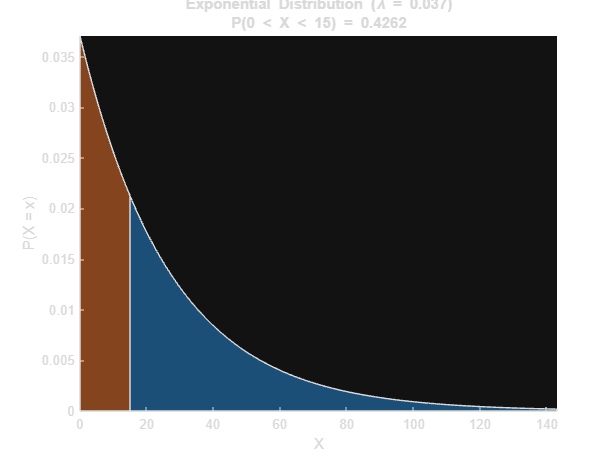

  
mu = 27; % mean arrival time
x1 = 0; % min of interval
x2 = 15; % max of interval
PlotExpDist(mu,x1,x2)

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Helper Functions

These functions plot the different distributions discussing in this script given their defining parameters and an interval of values.

function PlotUniformDist(a,b,x1,x2)
    % a min of distribution
    % b max of distribution
    % x1 min of interval
    % x2 max of interval
    
    h = 1/(b-a);
    figure
    hold on
    
    x = [a,x1,x1,a];
    y = [0,0,h,h];
    fill(x,y,"r","SeriesIndex",1,"FaceColor","flat",'FaceAlpha','0.5')
    
    x = [x1,x2,x2,x1];
    y = [0,0,h,h];
    fill(x,y,"r","SeriesIndex",2,"FaceColor","flat",'FaceAlpha','0.5')
    
    x = [x2,b,b,x2];
    y = [0,0,h,h];
    fill(x,y,"r","SeriesIndex",1,"FaceColor","flat",'FaceAlpha','0.5')
    
    p = round((x2-x1)*h,4);
    
    xticks(unique([a,b,x1,x2]))
    yticks(round(h,2))
    title({'Uniform Distribution',['P(',num2str(x1),' < X < ',num2str(x2),') = ',num2str(p)]})
    xlabel('X')
    ylabel('P(X = x)')
    
    hold off
    
end

function PlotNormalDist(mu,sigma,x1,x2)
    % mu is the mean of the distribution
    % sigma is the standard deviation of the distribution
    % x1 min of interval
    % x2 max of interval
    
    l = mu-4*sigma;
    r = mu+4*sigma;
    x = unique([(l:0.01:r),x1,x2]);
    y = normpdf(x,mu,sigma);
    p = round(normcdf(x2,mu,sigma)-normcdf(x1,mu,sigma),4);
    
    figure
    hold on
    
    left = find(x<=x1);
    middle = find(x>=x1 & x<=x2);
    right = find(x>=x2);
    fill([x(left),fliplr(x(left))],[zeros(1,numel(left)),fliplr(y(left))],"r","SeriesIndex",1,"FaceColor","flat",'FaceAlpha','0.5')
    fill([x(middle),fliplr(x(middle))],[zeros(1,numel(middle)),fliplr(y(middle))],"r","SeriesIndex",2,"FaceColor","flat",'FaceAlpha','0.5')
    fill([x(right),fliplr(x(right))],[zeros(1,numel(right)),fliplr(y(right))],"r","SeriesIndex",1,"FaceColor","flat",'FaceAlpha','0.5')
    
    axis([l,r,-inf,inf])
    xticks(l:sigma:r)
    title({['Normal Distribution (\mu = ',num2str(mu),', \sigma = ',num2str(sigma),')'],['P(',num2str(x1),' < X < ',num2str(x2),') = ',num2str(p)]})
    xlabel('X')
    ylabel('P(X = x)')
    
    hold off
    
end

function PlotExpDist(mu,x1,x2)
    % mu is the mean number of success per interval
    % x1 min of interval
    % x2 max of interval
    
    close all
    l=0;
    r=round(expinv(0.995,mu));
    
    res = 0.1;
    x = unique([(l:res:r),x1,x2]);
    y = exppdf(x,mu);
    p = round(expcdf(x2,mu)-expcdf(x1,mu),4);
    
    figure
    hold on
    left = find(x<=x1);
    middle = find(x>=x1 & x<=x2);
    right = find(x>=x2);
    fill([x(left),fliplr(x(left))],[zeros(1,numel(left)),fliplr(y(left))],"r","SeriesIndex",1,"FaceColor","flat",'FaceAlpha','0.5')
    fill([x(middle),fliplr(x(middle))],[zeros(1,numel(middle)),fliplr(y(middle))],"r","SeriesIndex",2,"FaceColor","flat",'FaceAlpha','0.5')
    fill([x(right),fliplr(x(right))],[zeros(1,numel(right)),fliplr(y(right))],"r","SeriesIndex",1,"FaceColor","flat",'FaceAlpha','0.5')
    
    axis([l,r,-inf,inf])
    title({['Exponential Distribution (\lambda = ',num2str(round(1/mu,4)),')'],['P(',num2str(x1),' < X < ',num2str(x2),') = ',num2str(p)]})
    xlabel('X')
    ylabel('P(X = x)')
    
    hold off
    
end